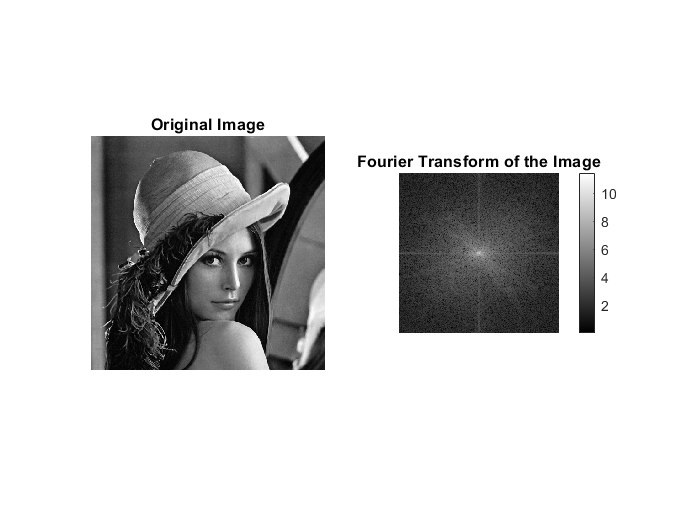

% Read the image and convert to grayscale
img = rgb2gray(imread('image.png'));

% Rescale image to the range [0 1]
I = im2double(img);

% Apply fast Fourier transform to the image
IFFT = fft2(I);

% Shift zero-frequency component to the center
IFFTShift = fftshift(IFFT);

% Compute the magnitude for display purposes
IFFTShiftMag = abs(IFFTShift);

% Display original image and its Fourier transform
figure;
subplot(1, 2, 1);
imshow(img);
title('Original Image');

subplot(1, 2, 2);
imshow(log(IFFTShiftMag + 1), []);
title('Fourier Transform of the Image');
colorbar;

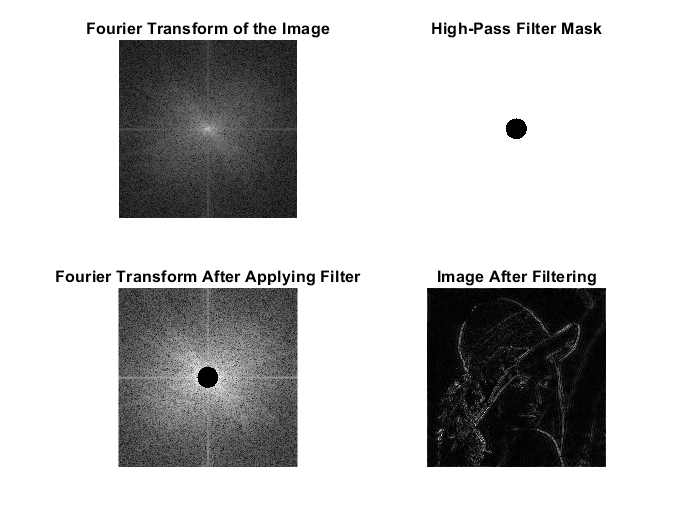


% Define high-pass filter mask
[M, N] = size(I);
[X, Y] = meshgrid(1:N, 1:M);
centerX = ceil(N/2);
centerY = ceil(M/2);
cutoff = 30;
mask = sqrt((X - centerX).^2 + (Y - centerY).^2) > cutoff;

% Apply high-pass filter to the Fourier transform
filteredImgFFT = IFFTShift .* mask;

% Compute the inverse Fourier transform to get the filtered image
filteredImg = ifft2(ifftshift(filteredImgFFT));

% Take the magnitude of the result and normalize to the range [0 1]
filteredImg = abs(filteredImg);
filteredImg = mat2gray(filteredImg);

% Display the results
figure;
subplot(2, 2, 1);
imshow(log(IFFTShiftMag + 1), []);
title('Fourier Transform of the Image');

subplot(2, 2, 2);
imshow(mask);
title('High-Pass Filter Mask');

subplot(2, 2, 3);
imshow(log(abs(filteredImgFFT) + 1), []);
title('Fourier Transform After Applying Filter');

subplot(2, 2, 4);
imshow(filteredImg, []);
title('Image After Filtering');

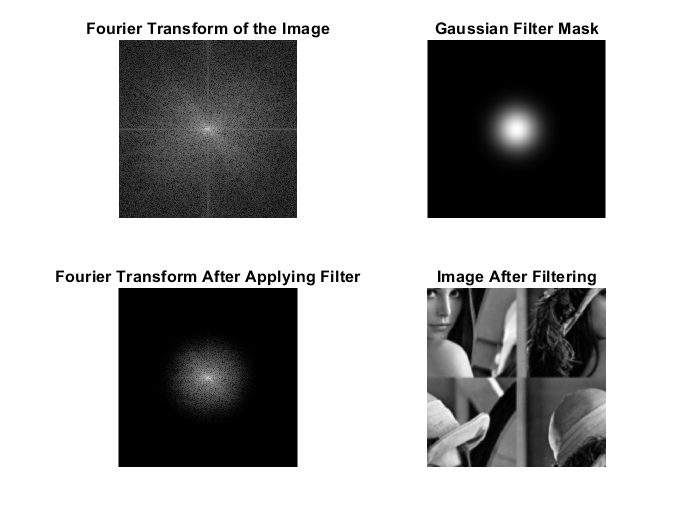


% Apply Fourier transform to the Gaussian filter
filterFFT = fft2(filter, size(I, 1), size(I, 2));
filterFFTShift = fftshift(filterFFT);
filterFFTShiftMag = abs(filterFFTShift);

% Apply Gaussian filter to the Fourier transform of the image
filteredImgFFT = IFFTShift .* filterFFTShift;

% Compute the inverse Fourier transform to get the filtered image
filteredImg = ifft2(ifftshift(filteredImgFFT));

% Take the magnitude of the result and normalize to the range [0 1]
filteredImg = abs(filteredImg);
filteredImg = mat2gray(filteredImg);

% Display the results
figure;
subplot(2, 2, 1);
imshow(log(IFFTShiftMag + 1), []);
title('Fourier Transform of the Image');

subplot(2, 2, 2);
imshow(filterFFTShiftMag, []);
title('Gaussian Filter Mask');

subplot(2, 2, 3);
imshow(log(abs(filteredImgFFT) + 1), []);
title('Fourier Transform After Applying Filter');

subplot(2, 2, 4);
imshow(filteredImg, []);
title('Image After Filtering');

## DCT

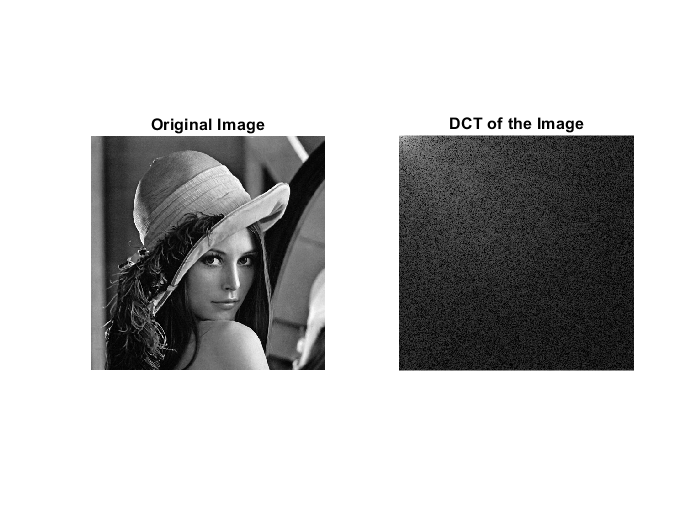

% Read the image and convert to grayscale
img = rgb2gray(imread('image.png'));

% get DCT of the image
J = dct2(img);

% Display original image and its DCT
figure;
subplot(1, 2, 1);
imshow(img);
title('Original Image');

subplot(1, 2, 2);
imshow(log(abs(J)+1), []);
title('DCT of the Image');

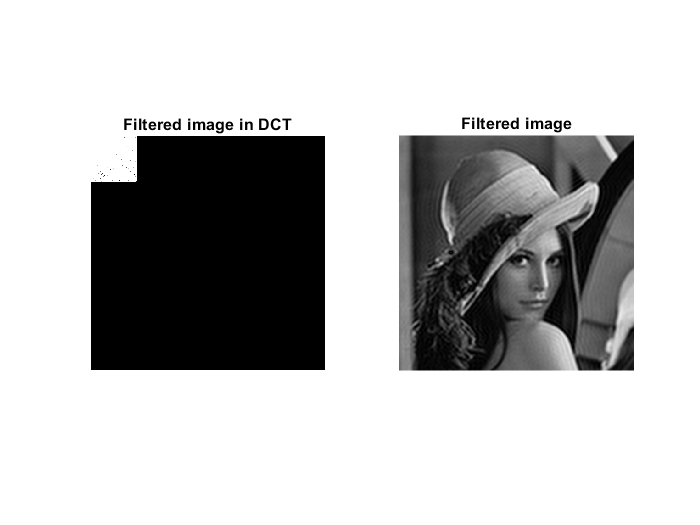


% apply filter
H = zeros(size(img));
H(1:100, 1:100) = 1;

F = H .* J;

% Display original image and its DCT
figure;
subplot(1, 2, 1);
imshow(log(abs(F) + 1));
title('Filtered image in DCT');

subplot(1, 2, 2);
imshow(mat2gray(abs(idct2(F))), []);
title('Filtered image');